# Evaluación 1

José Diego Tomé Guardado A01733345

**EJERCICIO 1:**

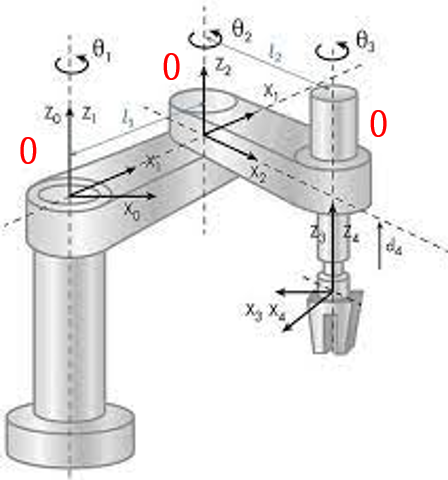 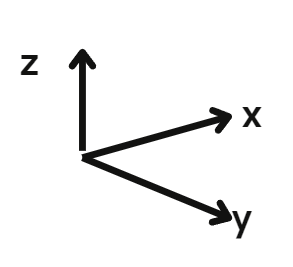

Para este primer ejercicio tenemos las variables tenemos la definición de las variables simbólicas donde th`1(t)`, th`2(t)` y th`3(t)`son la representación de las posiciones angulares de las articulaciones en función del tiempo. También vamos a tener en cuenta la configuración del robot con el vector de `RP` en que pondremos de 0 porque las juntas con las que cuenta nuestro robot son rotacionales. Tambièn es importante decir que h se tomará como la altura de nuestro base.

%Limpieza de pantalla
clear all
close all
clc

%Declaración de variables simbólicas (no tienen valor especifico)
syms th1(t) l1 
syms th2(t) l2
syms th3(t) l3
syms h %ponemos una h para indicar la altura 

RP=[0 0 0]; %configuracion del robot, 0 para junta rotacional y 1 para prismatica 

%Vector de coordenadas articulares
Q = [th1 th2 th3]; 
disp('Coordenadas articulares'); 

Coordenadas articulares


pretty(Q);

(th1(t), th2(t), th3(t))




%vector de velocidad articulares
Qp = diff(Q,t); %se utiliza diff para derivadas cuya variable no depende de otras
disp('Velocidades articulares'); 

Velocidades articulares


pretty(Qp); 

/  d          d          d        \
| -- th1(t), -- th2(t), -- th3(t) |
\ dt         dt         dt        /



%numero de grado de libertad del robot
GDL = size(RP,2); %se coloca 2 para referirse a las columnas de la matriz 
GDL_str = num2str(GDL); %convertir numero a string

Análisis de articulaciones

Para la articulacion 1 vamos a tomar en cuenta que correspondiente a nuestro marco referencial inercial podemos observar que nuestro eje y, ya esta correspondiente al movimiento que va a tener la primera junta rotacional. 


%Articulacion 1 
%posicion de la junta 1 respecto a 0
P(:,:,1) = [l1*cos(th1);
            l1*sin(th1); 
            0]; %vector de posicion indexado por pagina


% Definir la matriz de rotación original R(:,:,1)
R(:,:,1) = [cos(th1) -sin(th1) 0; 
            sin(th1) cos(th1) 0; 
             0           0     1];


Para la articulacion 2 vamos a ver que igualmente se encuentra bien definida en su posicion correcta y tambien la matriz de rotacion se encuentra correctamente en el eje z con la matriz de rotacion de z


%Articulación 2
%posicion de la junta 2 respecto a 1
P(:,:,2) = [l2*cos(th2);
            l2*sin(th2); 
            0];  %vector de posicion indexado por pagina

%matriz de rotacion de articulacion 2
R(:,:,2) = [cos(th2) -sin(th2) 0; %analisis de robot pendulo
            sin(th2) cos(th2)  0; 
            0        0         1];   

Para la articulacion 3 podemos ver que vamos a tener una rotacion por el eje de las z, por lo tanto tenemos claro que la ultima junta sera de revolucion y en este caso vamos a poner una variable que ya teniamos declarada como h solo para darle mas sentido a este paso, mientras que la matriz de rotacion la identificaremos como una matriz de identidad debido a que no existe otra articulacion en nuestro sistema.

%Articulación 3
%posicion de la junta 3 respecto a 2
P(:,:,3) = [0;0;h];  %vector de posicion indexado por pagina

%matriz de rotacion de articulacion 3
R(:,:,3) = [1  0 0;
            0  1 0;
            0  0 1];  

Vector_Zeros = zeros(1,3); 

%inicializamos matriz de transformacion homogenea local
A(:,:,GDL) = simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);

%inicializamos matriz de transformacion homogenea global ()
T(:,:,GDL) = simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);

PO(:,:,GDL)= P(:,:,GDL); %vectores de posicion vistos desde el marco de referencia inercial

RO(:,:,GDL)= R(:,:,GDL); %matrices de rotacion distas desde el marco de referencia inercial

for i= 1: GDL
    i_str = num2str(i);
    %locales
    disp(strcat('Matriz de transformacion local A',i_str));
    A(:,:,i)=simplify([R(:,:,i) P(:,:,i); Vector_Zeros 1]);
    pretty (A(:,:,i));

    %globales
    try 
        T(:,:,i) = T(:,:,i-1)*A(:,:,i);
    catch 
        T(:,:,i) = A(:,:,i); %caso especifico cuando i= 1 nos marcaria error en try
    end 
    disp(strcat('Matriz de transformacion global T',i_str));
    T(:,:,i) = simplify(T(:,:,i));
    pretty(T(:,:,i));

    %obtenemos la matriz de rotacion RO y el vector de translacion PO de la
    %matriz de transformacion homogenea global T(:,:,GDL)

    RO(:,:,i) = T(1:3,1:3,i);
    PO(:,:,i) = T(1:3,4,i);
    pretty(RO(:,:,i));
    pretty(PO(:,:,i));
end 

Matriz de transformacion local A1


/ cos(th1(t)), -sin(th1(t)), 0, l1 cos(th1(t)) \
|                                              |
| sin(th1(t)),  cos(th1(t)), 0, l1 sin(th1(t)) |
|                                              |
|      0,            0,      1,        0       |
|                                              |
\      0,            0,      0,        1       /



Matriz de transformacion global T1


/ cos(th1(t)), -sin(th1(t)), 0, l1 cos(th1(t)) \
|                                              |
| sin(th1(t)),  cos(th1(t)), 0, l1 sin(th1(t)) |
|                                              |
|      0,            0,      1,        0       |
|                                              |
\      0,            0,      0,        1       /



/ cos(th1(t)), -sin(th1(t)), 0 \
|                              |
| sin(th1(t)),  cos(th1(t)), 0 |
|                              |
\      0,            0,      1 /



/ l1 cos(th1(t)) \
|                |
| l1 sin(th1(t)) |
|                |
\        0       /



Matriz de transformacion local A2


/ cos(th2(t)), -sin(th2(t)), 0, l2 cos(th2(t)) \
|                                              |
| sin(th2(t)),  cos(th2(t)), 0, l2 sin(th2(t)) |
|                                              |
|      0,            0,      1,        0       |
|                                              |
\      0,            0,      0,        1       /



Matriz de transformacion global T2


/ #2, -#1, 0, l1 cos(th1(t)) + l2 #2 \
|                                    |
| #1,  #2, 0, l1 sin(th1(t)) + l2 #1 |
|                                    |
|  0,  0,  1,            0           |
|                                    |
\  0,  0,  0,            1           /

where

   #1 == sin(th1(t) + th2(t))

   #2 == cos(th1(t) + th2(t))




/ cos(th1(t) + th2(t)), -sin(th1(t) + th2(t)), 0 \
|                                                |
| sin(th1(t) + th2(t)),  cos(th1(t) + th2(t)), 0 |
|                                                |
\           0,                    0,           1 /



/ l1 cos(th1(t)) + l2 cos(th1(t) + th2(t)) \
|                                          |
| l1 sin(th1(t)) + l2 sin(th1(t) + th2(t)) |
|                                          |
\                     0                    /



Matriz de transformacion local A3


/ 1, 0, 0,  0 \
|             |
| 0, 1, 0,  0 |
|             |
| 0, 0, 1, l2 |
|             |
\ 0, 0, 0,  1 /



Matriz de transformacion global T3


/ #2, -#1, 0, l1 cos(th1(t)) + l2 #2 \
|                                    |
| #1,  #2, 0, l1 sin(th1(t)) + l2 #1 |
|                                    |
|  0,  0,  1,           l2           |
|                                    |
\  0,  0,  0,            1           /

where

   #1 == sin(th1(t) + th2(t))

   #2 == cos(th1(t) + th2(t))




/ cos(th1(t) + th2(t)), -sin(th1(t) + th2(t)), 0 \
|                                                |
| sin(th1(t) + th2(t)),  cos(th1(t) + th2(t)), 0 |
|                                                |
\           0,                    0,           1 /



/ l1 cos(th1(t)) + l2 cos(th1(t) + th2(t)) \
|                                          |
| l1 sin(th1(t)) + l2 sin(th1(t) + th2(t)) |
|                                          |
\                    l2                    /




%calculamos el jacobiano lineal de forma diferencial
disp('Jacobiano lineal obtenido de forma diferencial');

Jacobiano lineal obtenido de forma diferencial


%derivadas parciales de x con respecto a th1 y th2
Jv11= functionalDerivative(PO(1,1,GDL), th1);
Jv12= functionalDerivative(PO(1,1,GDL), th2);
Jv13= functionalDerivative(PO(1,1,GDL), th3);
%derivadas de y con respecto a th1 y th2
Jv21= functionalDerivative(PO(2,1,GDL), th1);
Jv22= functionalDerivative(PO(2,1,GDL), th2);
Jv23= functionalDerivative(PO(2,1,GDL), th3);
%parciales de z con respecto a th1 y th2
Jv31= functionalDerivative(PO(3,1,GDL), th1);
Jv32= functionalDerivative(PO(3,1,GDL), th2);
Jv33= functionalDerivative(PO(3,1,GDL), th3);

%creamos la matriz del jacobiano lineal
jv_d = simplify([Jv11 Jv12; ...
                Jv21 Jv22 ; ...
                Jv31 Jv32]); 

pretty(jv_d)

/ - l1 sin(th1(t)) - l2 sin(th1(t) + th2(t)), -l2 sin(th1(t) + th2(t)) \
|                                                                      |
|  l1 cos(th1(t)) + l2 cos(th1(t) + th2(t)),   l2 cos(th1(t) + th2(t)) |
|                                                                      |
\                      0,                                 0            /





%------------------------------------------------
%Calculamos el jacobiano lineal y angular de forma analitica
%inicializamod jacobianos analiticos (lineal y angular)
Jv_a(:,GDL)=PO(:,:,GDL);
Jw_a(:,GDL)=PO(:,:,GDL);

for k=1:GDL
    if((RP(k)==0)|(RP(k)==1))

        try
            Jv_a(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL)-PO(:,:,k-1)); %Producto cruz
            Jw_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)= cross([0,0,1], PO(:,:,GDL));
            Jw_a(:,k)=[0,0,1]; %No hay matriz de rotacion anterior, se imprime la matriz de identidad
        end
    else
        %articulaciones prismaticas
       try
           Jv_a(:,k)= RO(:,3,k-1);
       catch
           Jv_a(:,k)=[0,0,1];
       end
           Jw_a(:,k)=[0,0,0];
    end
end

Jv_a= simplify (Jv_a);
Jw_a= simplify (Jw_a);
disp('Jacobiano lineal obtenido de forma analítica');

Jacobiano lineal obtenido de forma analítica


pretty (Jv_a);

/ - l1 sin(th1(t)) - l2 sin(th1(t) + th2(t)), -l2 sin(th1(t) + th2(t)), 0 \
|                                                                         |
|  l1 cos(th1(t)) + l2 cos(th1(t) + th2(t)),   l2 cos(th1(t) + th2(t)), 0 |
|                                                                         |
\                      0,                                 0,            0 /



disp('Jacobiano ángular obtenido de forma analítica');

Jacobiano ángular obtenido de forma analítica


pretty (Jw_a);

/ 0, 0, 0 \
|         |
| 0, 0, 0 |
|         |
\ 1, 1, 1 /




disp('Velocidad lineal obtenida mediante el Jacobiano Lineal');

Velocidad lineal obtenida mediante el Jacobiano Lineal


V=simplify (Jv_a*Qp');
pretty(V);

/   _________                               _________    \
|    d                                       d           |
| - -- th1(t) (l1 sin(th1(t)) + l2 #1) - l2 -- th2(t) #1 |
|   dt                                      dt           |
|                                                        |
|  _________                               _________     |
|   d                                       d            |
|  -- th1(t) (l1 cos(th1(t)) + l2 #2) + l2 -- th2(t) #2  |
|  dt                                      dt            |
|                                                        |
\                            0                           /

where

   #1 == sin(th1(t) + th2(t))

   #2 == cos(th1(t) + th2(t))




disp('Velocidad angular obtenido mediante el Jacobiano angular')

Velocidad angular obtenido mediante el Jacobiano angular


W=simplify (Jw_a*Qp');
pretty(W);

/                 0                 \
|                                   |
|                 0                 |
|                                   |
| _________   _________   _________ |
|  d           d           d        |
| -- th1(t) + -- th2(t) + -- th3(t) |
\ dt          dt          dt        /



Observamos finalmente nuestros resultados, teniendo el vector de velocidades lineales que nos dice que sí existe el movimiento en `x` y `y` pero el movimiento en `z` se encuentra en cero, no teniendo velocidad lineal en z. Caso contrario de la velocidad angular que se observa que tenemos cero en los ejes de `x` y `y `pero si encontramos con que tenemos velocidad angular en el eje `z` que será la suma de las derivadas con respecto a *t* de las posiciones angulares de las articulaciones en la función del tiempo `th1(t)` y `th2(t) y th3(t)` indicando rotación solo en `z. `Se representan correctamente las velocidades tanto lineales como angulares en función de las velocidades articulares, son completamente importantes para poder comprender cómo se mueve el extremo del robot con repuestos a los cambios de posición de sus articulaciones.

**EJERCICIO 2:**

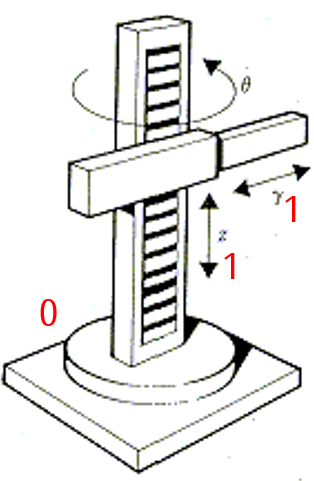 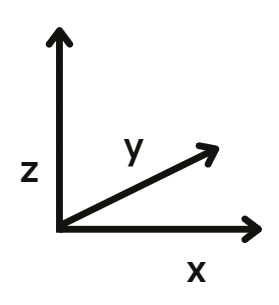

Para el segundo ejercicio vamos a tener también las variables simbólicas donde th`1(t)`, th`2(t)` y th`3(t) `son la representación de las posiciones angulares de las articulaciones en función del tiempo pero tambien definiremos l1,l2 y l3 debido a que lo ocuparemos para las juntas prismaticas mientras que theta para las rotacionales. También vamos a tener en cuenta la configuración del robot con el vector de `RP` en que pondremos de 0 porque las juntas con las que cuenta nuestro robot son rotacionales. También es importante decir que h se tomará como la altura de nuestro base.

%Limpieza de pantalla
clear all
close all
clc

%Declaración de variables simbólicas (no tienen valor especifico)
syms th1(t) l1 
syms th2(t) l2
syms th3(t) l3
syms h

RP=[0 1 1]; %configuracion del robot, 0 para junta rotacional y 1 para prismatica 

%Vector de coordenadas articulares
Q = [th1 l2 l3]; 
disp('Coordenadas articulares'); 

Coordenadas articulares


pretty(Q);

(th1(t), l2, l3)




%vector de velocidad articulares
Qp = diff(Q,t); %se utiliza diff para derivadas cuya variable no depende de otras
disp('Velocidades articulares'); 

Velocidades articulares


pretty(Qp); 

/  d              \
| -- th1(t), 0, 0 |
\ dt              /




%numero de grado de libertad del robot
GDL = size(RP,2); %se coloca 2 para referirse a las columnas de la matriz 
GDL_str = num2str(GDL); %convertir numero a string


Para la articulacion 1 vamos a tomar en cuenta que correspondiente a nuestro marco referencial inercial podemos observar que nuestro eje y, ya esta correspondiente al movimiento que va a tener la primera junta rotacional. Es por ello que pondremos en el eje z cualquier variable definida como h solo para darle sentido a la explicación de nuestra articulaciòn.

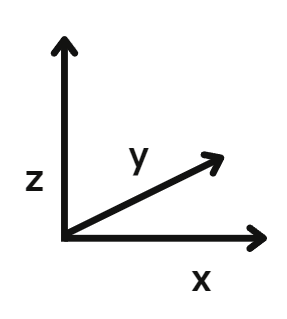

%Articulacion 1 
%posicion de la junta 1 respecto a 0
P(:,:,1) = [0;
            0; 
            h];  %vector de posicion indexado por pagina

% Definir la matriz de rotación original R(:,:,1)
R(:,:,1) = [cos(th1) -sin(th1) 0; 
            sin(th1) cos(th1) 0; 
             0           0     1];

Para la segunda articulacion ya tendremos una rotacion del eje x en -90 grados y es por ello que rotaremos nuestro eje x en -90. Bueno correspondiente al anterior marco de referencia tenemos que l2 va a estar definido en nuestro eje Z. 

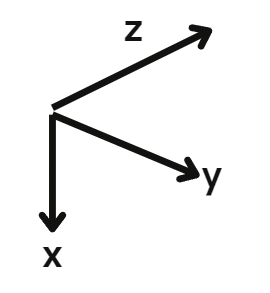

%Articulación 2
%posicion de la junta 3 respecto a 2
P(:,:,2) = [0; 0; l2];

%matriz de rotacion de X -90 grados
R(:,:,2) = [1  0 0;
           0  0 1;
           0 -1 0];


Por último para la articulación 3 vamos a tener que l3 se va a encontrar en el eje z debido a que es la tercer articulacion y por ello se define ahi, y como ya no tenemos otra articulacion, además de que l3 se encuentra ya correspondiente a esa articulacion procedemos a poner nuestra matriz de identidad debido a que no existe algo mas de otra articulacion.

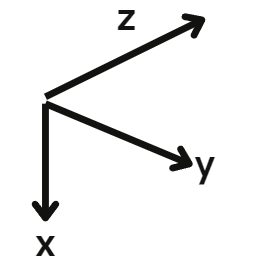

%Articulación 3
%posicion de la junta 3 respecto a 2
P(:,:,3) = [0; 0; l3];

%matriz de identidad
R(:,:,3) = [1  0 0;
            0  1 0;
            0  0 1];

Vector_Zeros = zeros(1,3); 

%inicializamos matriz de transformacion homogenea local
A(:,:,GDL) = simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);

%inicializamos matriz de transformacion homogenea global ()
T(:,:,GDL) = simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);

PO(:,:,GDL)= P(:,:,GDL); %vectores de posicion vistos desde el marco de referencia inercial

RO(:,:,GDL)= R(:,:,GDL); %matrices de rotacion distas desde el marco de referencia inercial

for i= 1: GDL
    i_str = num2str(i);
    %locales
    disp(strcat('Matriz de transformacion local A',i_str));
    A(:,:,i)=simplify([R(:,:,i) P(:,:,i); Vector_Zeros 1]);
    pretty (A(:,:,i));

    %globales
    try 
        T(:,:,i) = T(:,:,i-1)*A(:,:,i);
    catch 
        T(:,:,i) = A(:,:,i); %caso especifico cuando i= 1 nos marcaria error en try
    end 
    disp(strcat('Matriz de transformacion global T',i_str));
    T(:,:,i) = simplify(T(:,:,i));
    pretty(T(:,:,i));

    %obtenemos la matriz de rotacion RO y el vector de translacion PO de la
    %matriz de transformacion homogenea global T(:,:,GDL)

    RO(:,:,i) = T(1:3,1:3,i);
    PO(:,:,i) = T(1:3,4,i);
    pretty(RO(:,:,i));
    pretty(PO(:,:,i));
end 

Matriz de transformacion local A1


/ cos(th1(t)), -sin(th1(t)), 0, 0 \
|                                 |
| sin(th1(t)),  cos(th1(t)), 0, 0 |
|                                 |
|      0,            0,      1, h |
|                                 |
\      0,            0,      0, 1 /



Matriz de transformacion global T1


/ cos(th1(t)), -sin(th1(t)), 0, 0 \
|                                 |
| sin(th1(t)),  cos(th1(t)), 0, 0 |
|                                 |
|      0,            0,      1, h |
|                                 |
\      0,            0,      0, 1 /



/ cos(th1(t)), -sin(th1(t)), 0 \
|                              |
| sin(th1(t)),  cos(th1(t)), 0 |
|                              |
\      0,            0,      1 /



/ 0 \
|   |
| 0 |
|   |
\ h /



Matriz de transformacion local A2


/ 1,  0, 0,  0 \
|              |
| 0,  0, 1,  0 |
|              |
| 0, -1, 0, l2 |
|              |
\ 0,  0, 0,  1 /



Matriz de transformacion global T2


/ cos(th1(t)),  0, -sin(th1(t)),    0   \
|                                       |
| sin(th1(t)),  0,  cos(th1(t)),    0   |
|                                       |
|      0,      -1,       0,      h + l2 |
|                                       |
\      0,       0,       0,         1   /



/ cos(th1(t)),  0, -sin(th1(t)) \
|                               |
| sin(th1(t)),  0,  cos(th1(t)) |
|                               |
\      0,      -1,       0      /



/    0   \
|        |
|    0   |
|        |
\ h + l2 /



Matriz de transformacion local A3


/ 1, 0, 0,  0 \
|             |
| 0, 1, 0,  0 |
|             |
| 0, 0, 1, l3 |
|             |
\ 0, 0, 0,  1 /



Matriz de transformacion global T3


/ cos(th1(t)),  0, -sin(th1(t)), -l3 sin(th1(t)) \
|                                                |
| sin(th1(t)),  0,  cos(th1(t)),  l3 cos(th1(t)) |
|                                                |
|      0,      -1,       0,           h + l2     |
|                                                |
\      0,       0,       0,             1        /



/ cos(th1(t)),  0, -sin(th1(t)) \
|                               |
| sin(th1(t)),  0,  cos(th1(t)) |
|                               |
\      0,      -1,       0      /



/ -l3 sin(th1(t)) \
|                 |
|  l3 cos(th1(t)) |
|                 |
\      h + l2     /




%calculamos el jacobiano lineal de forma diferencial
disp('Jacobiano lineal obtenido de forma diferencial');

Jacobiano lineal obtenido de forma diferencial


%derivadas parciales de x con respecto a th1 y th2
Jv11= functionalDerivative(PO(1,1,GDL), th1);
Jv12= functionalDerivative(PO(1,1,GDL), th2);
%derivadas de y con respecto a th1 y th2
Jv21= functionalDerivative(PO(2,1,GDL), th1);
Jv22= functionalDerivative(PO(2,1,GDL), th2);
%parciales de z con respecto a th1 y th2
Jv31= functionalDerivative(PO(3,1,GDL), th1);
Jv32= functionalDerivative(PO(3,1,GDL), th2);

%creamos la matriz del jacobiano lineal
jv_d = simplify([Jv11 Jv12; ...
                Jv21 Jv22 ; ...
                Jv31 Jv32]); 

pretty(jv_d)

/ -l3 cos(th1(t)), 0 \
|                    |
| -l3 sin(th1(t)), 0 |
|                    |
\        0,        0 /





%------------------------------------------------
%Calculamos el jacobiano lineal y angular de forma analitica
%inicializamod jacobianos analiticos (lineal y angular)
Jv_a(:,GDL)=PO(:,:,GDL);
Jw_a(:,GDL)=PO(:,:,GDL);

for k=1:GDL
    if((RP(k)==0)|(RP(k)==1))

        try
            Jv_a(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL)-PO(:,:,k-1)); %Producto cruz
            Jw_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)= cross([0,0,1], PO(:,:,GDL));
            Jw_a(:,k)=[0,0,1]; %No hay matriz de rotacion anterior, se imprime la matriz de identidad
        end
    else
        %articulaciones prismaticas
       try
           Jv_a(:,k)= RO(:,3,k-1);
       catch
           Jv_a(:,k)=[0,0,1];
       end
           Jw_a(:,k)=[0,0,0];
    end
end

Jv_a= simplify (Jv_a);
Jw_a= simplify (Jw_a);
disp('Jacobiano lineal obtenido de forma analítica');

Jacobiano lineal obtenido de forma analítica


pretty (Jv_a);

/ -l3 cos(th1(t)), -l3 cos(th1(t)), 0 \
|                                     |
| -l3 sin(th1(t)), -l3 sin(th1(t)), 0 |
|                                     |
\        0,               0,        0 /



disp('Jacobiano ángular obtenido de forma analítica');

Jacobiano ángular obtenido de forma analítica


pretty (Jw_a);

/ 0, 0, -sin(th1(t)) \
|                    |
| 0, 0,  cos(th1(t)) |
|                    |
\ 1, 1,       0      /




disp('Velocidad lineal obtenida mediante el Jacobiano Lineal');

Velocidad lineal obtenida mediante el Jacobiano Lineal


V=simplify (Jv_a*Qp');
pretty(V);

/     _________             \
|      d                    |
| -l3 -- th1(t) cos(th1(t)) |
|     dt                    |
|                           |
|     _________             |
|      d                    |
| -l3 -- th1(t) sin(th1(t)) |
|     dt                    |
|                           |
\             0             /



disp('Velocidad angular obtenido mediante el Jacobiano angular')

Velocidad angular obtenido mediante el Jacobiano angular


W=simplify (Jw_a*Qp');
pretty(W)

/     0     \
|           |
|     0     |
|           |
| _________ |
|  d        |
| -- th1(t) |
\ dt        /



Los resultados obtenidos para la velocidad lineal observamos que tendremos nula nuestra z por lo que podemos inferir que puede causar un error en este caso debido a que no corresponderia al movimiento del robot, mientra que tendremos que tener una articulacion efectuando para z la cual seria l2 debido a que es la que se estaria movimiento y causando un desplazamiento por lo que quedaria como la derivada de nuestra l2(t). Para el caso de los ejes de x,y tenemos tambien que se ven afectados por coseno y seno ya que se tiene un rotacion en estos mismos ejes debido al marco de referencia inercial.

Podemos ver que la velocidad angular vamos a tenerla en th1(t) debido a que contamos solo con una junta rotacional y se efectua en z, es por ello que solo existe en este eje mientras que para el eje x,y lo tenemos como 0 debido a que tenemos las juntas prismaticas y no significa una rotacion para estos ejes en este caso de la velocidad angular. Tambien ninguna otra junta podemos ver que rote sobre los demas ejes.